# Linear Transformations

## Review of Linear Transformations

A transformation *T* from $\mathbb{R}^n$ to $\mathbb{R}^m$ is a rule that assigns to each vector *x* in $\mathbb{R}^n$ a vector

*T(x)* in $\mathbb{R}^m$. The set $\mathbb{R}^n$ is called the domain of* T* and $\mathbb{R}^m$ is called the codomain of *T*.

## Definition of linear transformations 

A transformation* T* is linear if:

    (i) *T*(u + v) = *T*(u) + *T*(v) for all u; v in the domain of *T*;

    (ii) *T*(cu) = c*T* (u) for all scalars c and all u in the domain of *T*.

Note: Every matrix transformation is a linear transformation and satifies (i) and (ii).

## Linear Transformations in MATLAB

Suppose we have a set of coordinates, X, and we want to transform it linearly in some fashion with a matrix A. Firstly, download the datasets `logox.txt' and `logoy.txt' and put them into your current MATLAB folder.

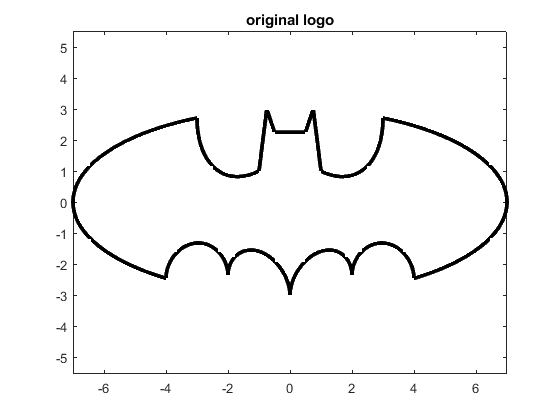

X = [ csvread('logox.txt') ; csvread('logoy.txt') ];
figure; plot(X(1, : ), X(2, : ), 'k', 'LineWidth', 3 ); title('original logo'), axis equal;

You  should know how to perform the most used transformations, such as rotations, reflections, scaling, shearing, and projects. These transformation matrices are given below as a quick reference.

### **Rotation**

To rotate by angle $\theta$ counterclockwise, set your transformation matrix A as


$$A= \left[\matrix{ \cos \theta & -\sin \theta \cr \sin \theta & \cos\theta} \right]$$


theta = pi/4; 
A = [cos(theta) -1*sin(theta); sin(theta) cos(theta)]

A =     0.7071   -0.7071
    0.7071    0.7071


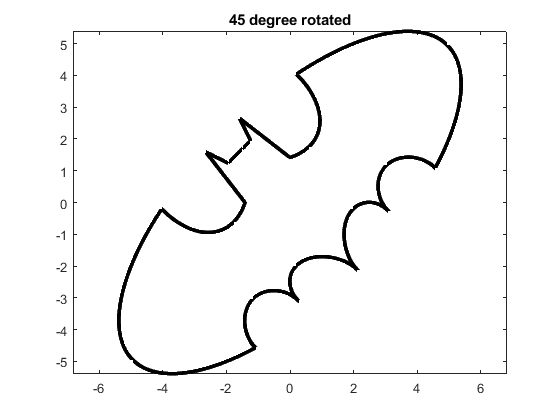

Y_rot = A*X;
figure; plot(Y_rot(1, : ), Y_rot(2, : ), 'k', 'LineWidth', 3 ), title('45 degree rotated'), axis equal;

### **Reflection**: 

Reflection against the x-axis , set your transformation matrix A as:


$$A= \left[\matrix{ 1 & 0 \cr 0 & -1} \right]$$


Reflection against the y-axis, set your transformation matrix A as:


$$A= \left[\matrix{ -1 & 0 \cr 0 & 1} \right]$$


Reflection against the line $y=x$, set your transformation matrix A as:


$$A= \left[\matrix{ 0 & 1 \cr 1 & 0} \right]$$


Reflection against the origin, set your transformation matrix A as:


$$A= \left[\matrix{ -1 & 0 \cr 0 & -1} \right]$$


A = [1 0; 0 -1]

A =      1     0
     0    -1


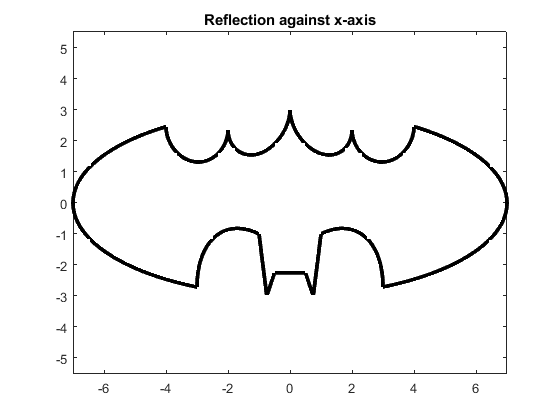

Y_refX = A*X;
figure; plot(Y_refX(1, : ), Y_refX(2, : ), 'k', 'LineWidth', 3 );title('Reflection against x-axis'), axis equal;

A = [-1 0; 0 1]

A =     -1     0
     0     1


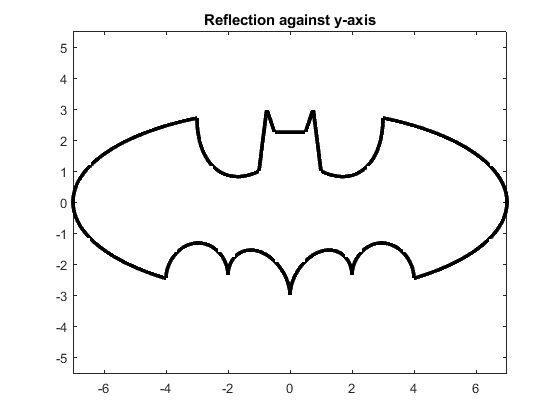

Y_refY = A*X;
figure; plot(Y_refY(1, : ), Y_refY(2, : ), 'k', 'LineWidth', 3 );title('Reflection against y-axis'), axis equal;

A = [0 1; 1 0]

A =      0     1
     1     0


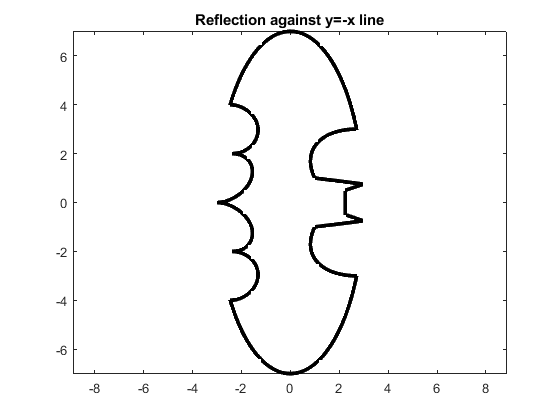

Y_refYX = A*X;
figure; plot(Y_refYX(1, : ), Y_refYX(2, : ), 'k', 'LineWidth', 3 );title('Reflection against y=-x line'), axis equal;

A = [-1 0 ; 0 -1]

A =     -1     0
     0    -1


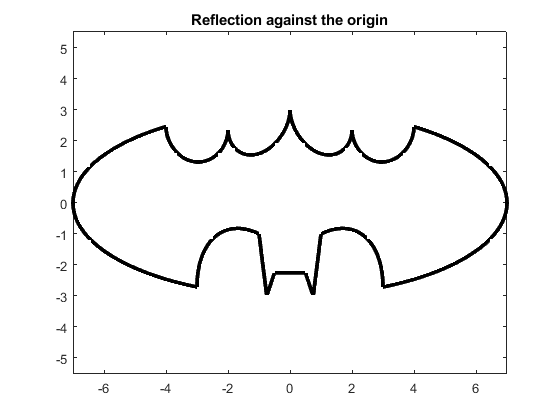

Y_refO = A*X;
figure; plot(Y_refO(1, : ), Y_refO(2, : ), 'k', 'LineWidth', 3 );title('Reflection against the origin'), axis equal;

### Scaling

To scale by length a in all directions, set your transformation matrix A as:


$$A= \left[\matrix{ a & 0 \cr 0 & a} \right]$$


sc = 3; % scale factor
A = [sc 0; 0 sc]

A =      3     0
     0     3


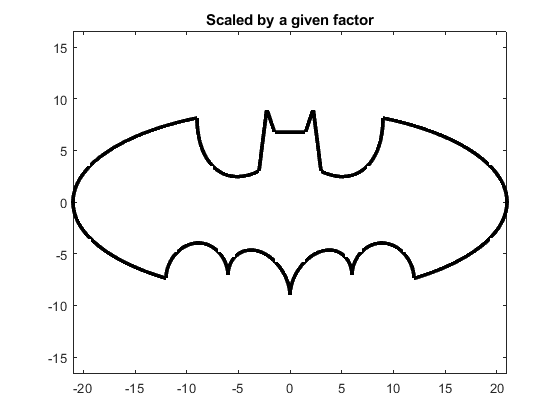

Y_sc = A*X;
figure; plot(Y_sc(1, : ), Y_sc(2, : ), 'k', 'LineWidth', 3 );title('Scaled by a given factor'), axis equal;

### Shear 

To shear by length b in the horizontal direction, set your transformation matrix A as:


$$A= \left[\matrix{ 1 & b \cr 0 & 1} \right]$$


To shear by length b in the vertical direction, set your transformation matrix A as:


$$A= \left[\matrix{ 1 & 0 \cr b & 1} \right]$$


b = 2;
A = [1 b; 0 1]

A =      1     2
     0     1


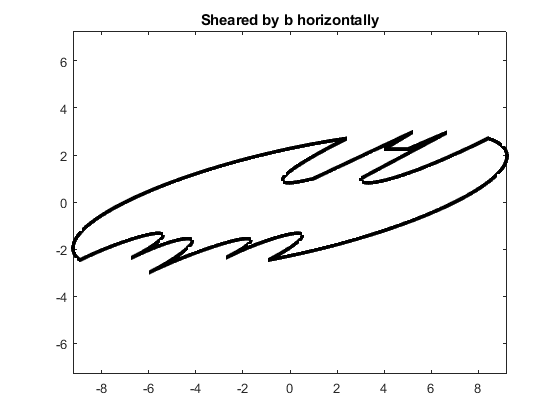

Y_shH = A*X;
figure; plot(Y_shH(1, : ), Y_shH(2, : ), 'k', 'LineWidth', 3 );title('Sheared by b horizontally'), axis equal;

A = [1 0; b 1]

A =      1     0
     2     1


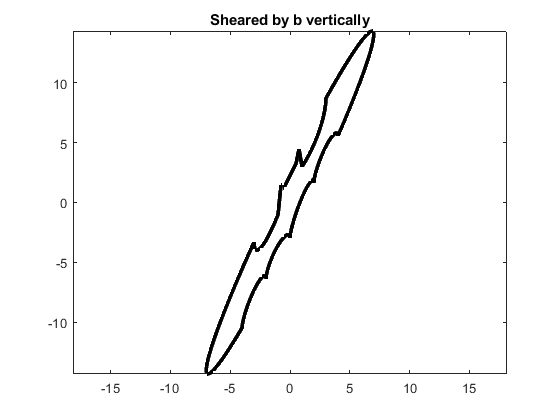

Y_shV = A*X;
figure; plot(Y_shV(1, : ), Y_shV(2, : ), 'k', 'LineWidth', 3 );title('Sheared by b vertically'), axis equal;

### Projection

To project to the x-axis, set your transformation matrix A as:


$$A= \left[\matrix{ 1 & 0 \cr 0 & 0} \right]$$


To project to the y-axis, set your transformation matrix A as:


$$A= \left[\matrix{ 0 & 0 \cr 0 & 1} \right]$$


A = [1  0 ; 0 0]

A =      1     0
     0     0


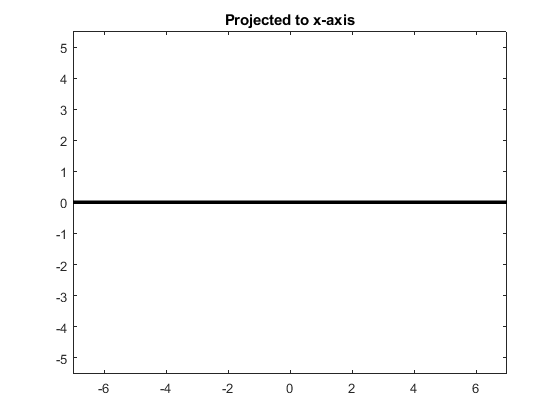

Y_prX = A*X;
figure; plot(Y_prX(1, : ), Y_prX(2, : ), 'k', 'LineWidth', 3 );title('Projected to x-axis'), axis equal;

A = [0  0 ; 0 1]

A =      0     0
     0     1


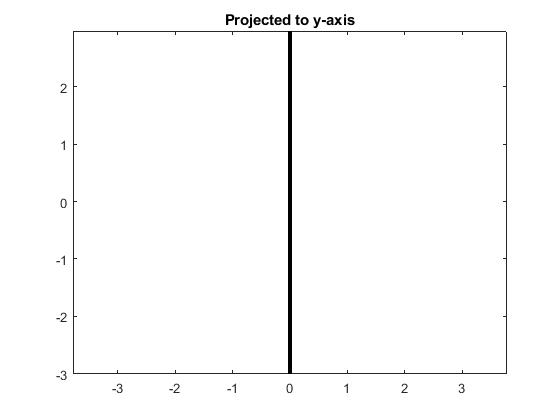

Y_prY = A*X;
figure; plot(Y_prY(1, : ), Y_prY(2, : ), 'k', 'LineWidth', 3 );title('Projected to y-axis'), axis equal;

Note: You can find more about linear transformation in wikipedia page:

https://en.wikipedia.org/wiki/Linear_map#Examples_of_linear_transformation_matrices